%calculating the mean first passage time using Gillespie simulations 
%to investigate the effect of branch migration domain length on RNA/DNA
%toehold exchange kinetics including spontaneous incumbent dissociation

%b = 20 %define branch migration domain length

b = 20

g2 = 2 %define incumbent toehold length

g2 = 2

g = 3 %define invader toehold length

g = 3


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -1*R*temp

dGrd = -0.5924

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(1,30)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(30, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(30, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 30)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 30)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,30)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    bg2 = b + g2 %branch migration domain + incumbent toehold length
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1   
    
    
    first_pass_time = zeros(1,N)
    
    %create arrays of forward and reverse transition rates
    if g == 1
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_Cr, [1 b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
        
        %define spontaneous incumbent dissociation rates
        Koff = [0, 0]; 
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])])
    else
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-1]), repmat(k_DEij, [1, g2-1]), k_EF, k_FF]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, repmat(k_Cr, [1, b-1]), k_DC, repmat(k_DEji, [1, g2-1]), k_FE]
            
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g+1])];
        for n = bg2-1:-1:g2+1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g2+1])])      
    end
    
    totalrate = Kf + Kb + Koff; %define total rate
    Pf = Kf./totalrate; %probability of forward transition
    Poff = Koff./totalrate; %probability of spontaneous incumbent dissociation
    Pb = 1- (Pf + Poff); %probability of reverse transition
    %loop through simulations
    for n = 1:N 
        state = 1; %initial state
        t = 0; %initial time 
        %restrict to possible states
        while (state >=1 && state < (2 + g + b + g2)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition 
            prob = rand();
            %select transition 
            if prob <= Pf(state) 
                state = state +1; %update state forward
            elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                state = 2 + g + b + g2; %update state for spontaneous incumbent dissociation
            else 
                state = state -1; %update state backward
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(b-9,n) = first_pass_time(n);
        ind_k_eff(b-9,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(b-9) = std(ind_first_pass_time(b-9, :))/sqrt(N); %calculate standard error
    std_err_k_eff(b-9) = std(ind_k_eff(b-9, :))/sqrt(N);
    std_err_log_k(b-9) = std(log10(ind_k_eff(b-9,:))/sqrt(N));
    avr_first_pass_time(b-9) = mean(first_pass_time) %calculate average first passage time
    k_eff(b-9) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

bg2 = 12

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 13

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032    1.8713         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 14

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032    1.8713    1.1305         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 15

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032    1.8713    1.1305    1.2394         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 16

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032    1.8713    1.1305    1.2394    1.2758         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 17

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032    1.8713    1.1305    1.2394    1.2758    1.9296         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 18

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb = 	1.0e+07 *

         0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff = 	1.0e+04 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 19

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 20

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 21

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 22

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.0000


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000         0


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 27

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345


Kb =          0    0.1598    0.1598    0.1598    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0000    5.4000


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 28

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0003


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 29

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 30

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260         0         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359         0         0         0         0         0         0         0         0         0         0         0


bg2 = 31

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076         0         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616         0         0         0         0         0         0         0         0         0         0


bg2 = 32

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772         0         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623         0         0         0         0         0         0         0         0         0


bg2 = 33

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010         0         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578         0         0         0         0         0         0         0         0


bg2 = 34

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093         0         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979         0         0         0         0         0         0         0


bg2 = 35

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681         0         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542         0         0         0         0         0         0


bg2 = 36

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678         0         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289         0         0         0         0         0


bg2 = 37

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678   24.7323         0         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289    0.8087         0         0         0         0


bg2 = 38

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678   24.7323   16.9497         0         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289    0.8087    1.1800         0         0         0


bg2 = 39

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678   24.7323   16.9497   16.6781         0         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289    0.8087    1.1800    1.1992         0         0


bg2 = 40

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678   24.7323   16.9497   16.6781   12.2461         0


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289    0.8087    1.1800    1.1992    1.6332         0


bg2 = 41

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678   24.7323   16.9497   16.6781   12.2461   24.0710


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289    0.8087    1.1800    1.1992    1.6332    0.8309


bg2 = 42

k_AB1 = 0.2005

k_B1A = 1.5984e+06

ans = 4.3448e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 331.7875

k_FE = 0

k_FF = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    1.5984    1.5984    1.5984    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Koff =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666


avr_first_pass_time =    19.9368   10.6876   17.6917   16.1367   15.6763   10.3649   23.9974   13.0637    5.9804    9.7803   14.9794   12.1397   15.6183   16.6751   20.4239   19.6887   20.9820   20.0576   12.2260   12.8076   13.6772   15.9010   15.4093   12.8681   11.5678   24.7323   16.9497   16.6781   12.2461   24.0710


k_eff =     1.0032    1.8713    1.1305    1.2394    1.2758    1.9296    0.8334    1.5310    3.3442    2.0449    1.3352    1.6475    1.2805    1.1994    0.9792    1.0158    0.9532    0.9971    1.6359    1.5616    1.4623    1.2578    1.2979    1.5542    1.7289    0.8087    1.1800    1.1992    1.6332    0.8309


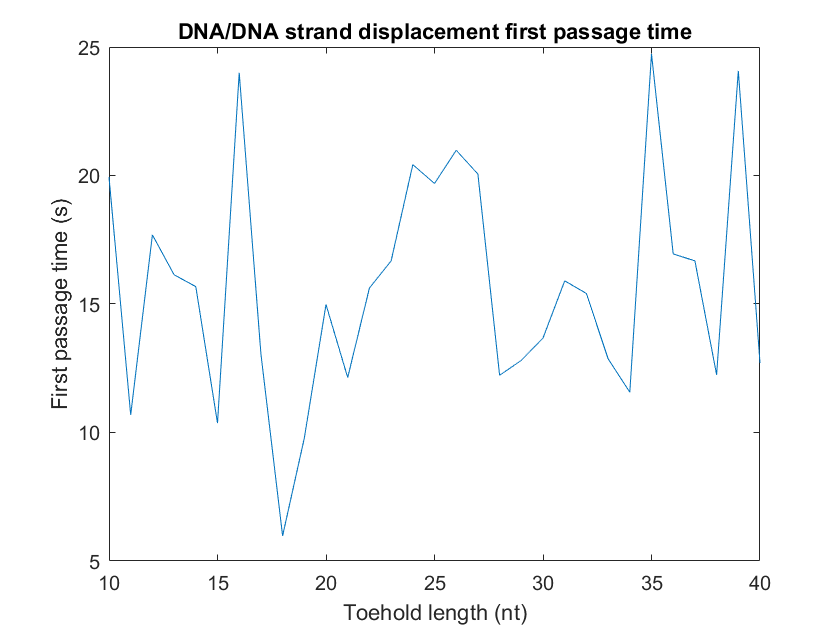

plot(10:40, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

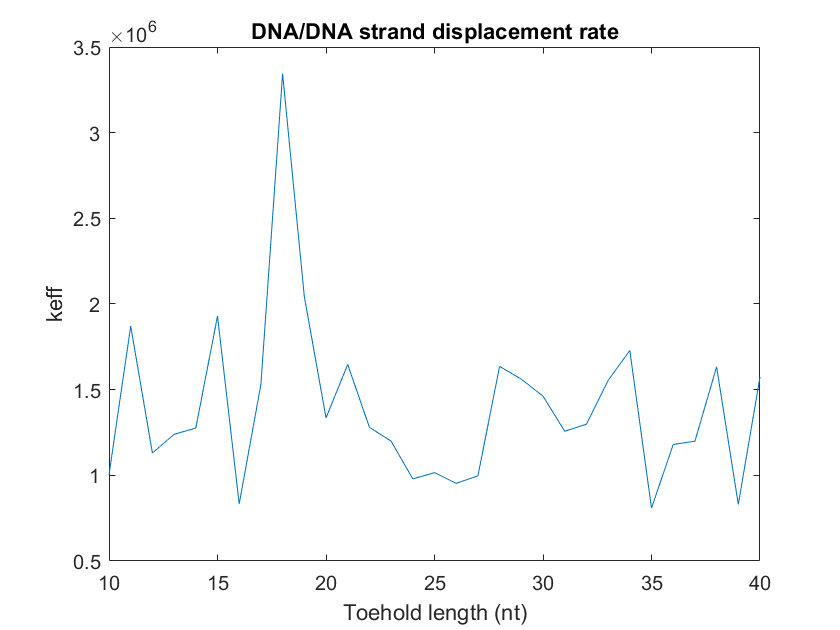


plot(10:40, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

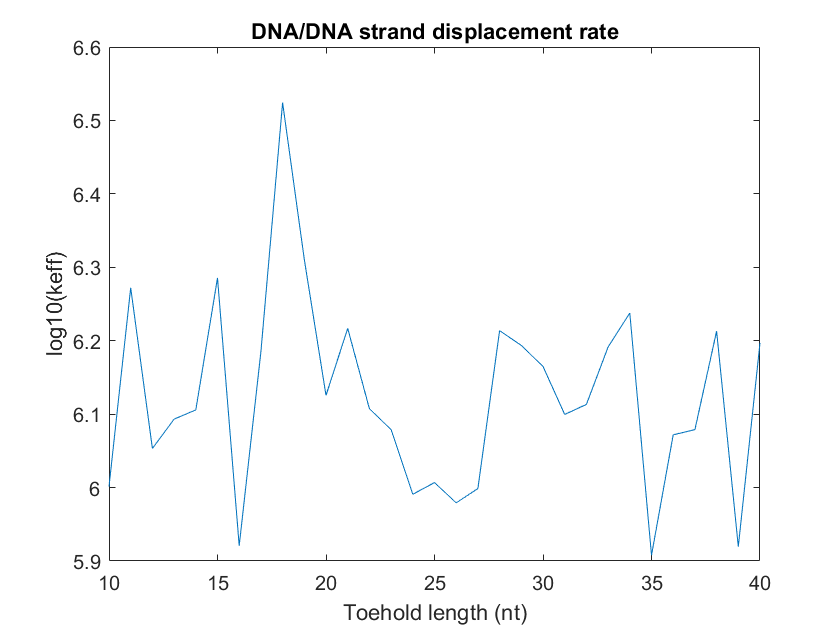


plot(10:40, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

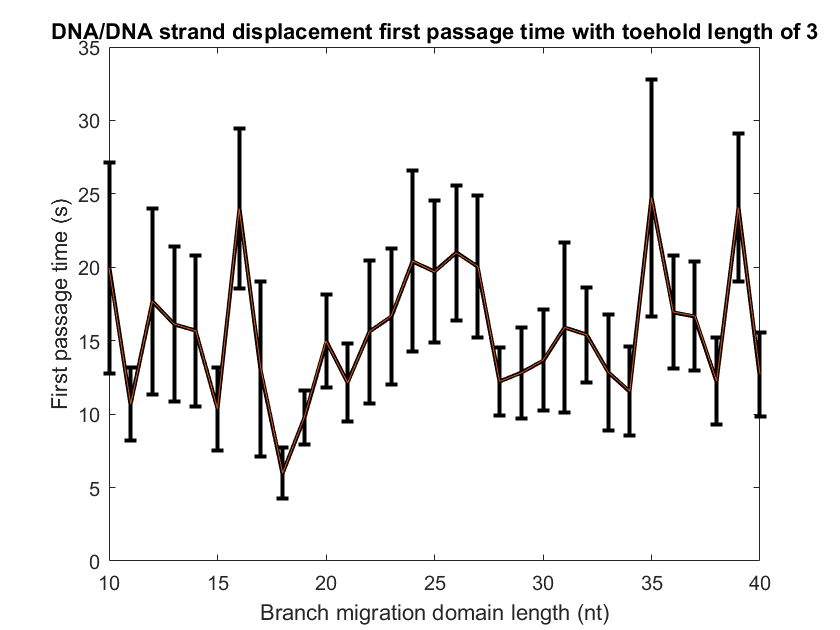


errorbar(10:40, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(10:40, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

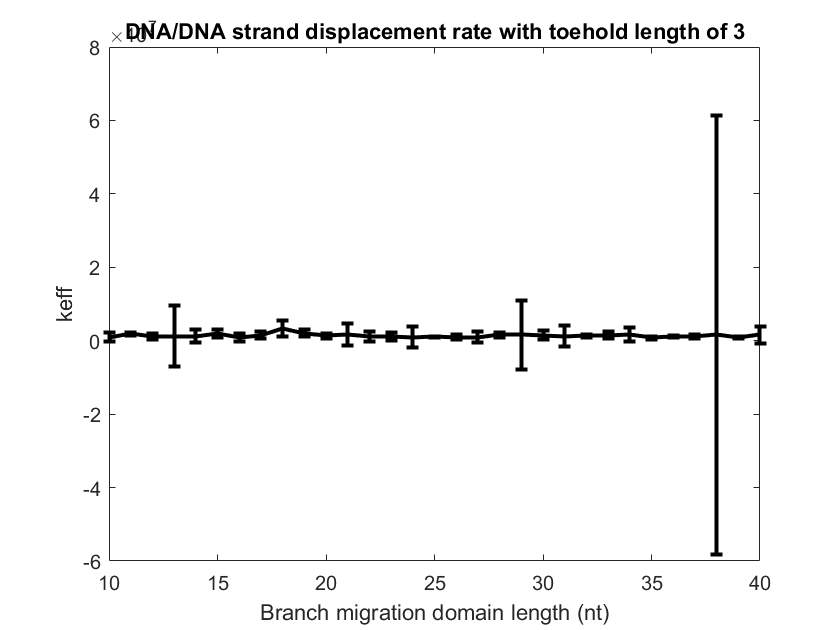


errorbar(10:40, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off

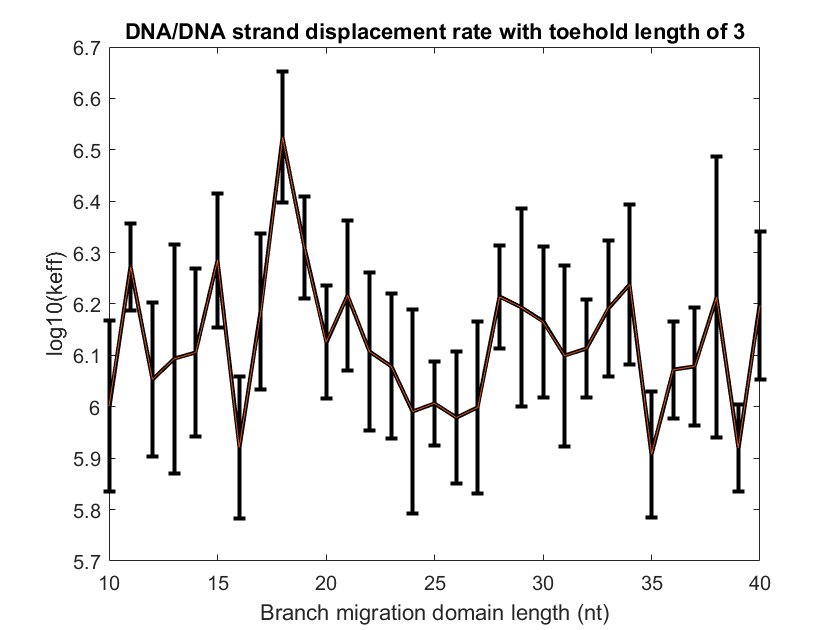


errorbar(10:40, log10(k_eff), std_err_log_k, 'k', 'linewidth', 2)
hold on
plot(10:40, log10(k_eff), '', 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off